Instead of using AR coefficients,  we can directly use the recordings



num_iter = 5; % number of max iterations
%iniitial setup

alpha = 1;
beta = 1;
ti = 1;

n_nodes = 30;


X_test = squeeze(data_two_drives(ti,1:n_nodes,:));

%first 61 electrodes for now
%X_test = a_coefficients_electrodes(1:n_nodes,:);
Y0 = X_test;

n_data = size(X_test,2);

M = full(DuplicationM(n_nodes));

%initialize parameters
Y = Y0;
vechL_0.vechL = ones(n_nodes * (n_nodes + 1) / 2, 1);
Y_0.Y_opt = zeros([n_nodes,n_data]);

[L_iter,Y,vechl_result, Y_result] = cal_GLSigRep(X_test, n_data, Y_0, M, alpha, num_iter, Y, beta, n_nodes, vechL_0);


Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Problem appears unbounded.

fminunc stopped because the objective function value is less than
or equal to the value of the objective function limit.

<stopping criteria details>
Finished 1 iteration with -554074610100585365504.00  and -554074610071161929728.00
Solving problem using fminco


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Problem appears unbounded.

fminunc stopped because the objective function value is less than
or equal to the value of the objective function limit.

<stopping criteria details>
Finished 2 iteration with -220916566770881593344.00  and -220916566741458157568.00
Solving problem using fmincon.



Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solving problem using fminunc.

Solver stopped prematurely.

fminunc stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 6.000000e+05.

Finished 3 iteration with 288834479690832.69  and 288835514742847.38
Solving problem using fmincon.

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.

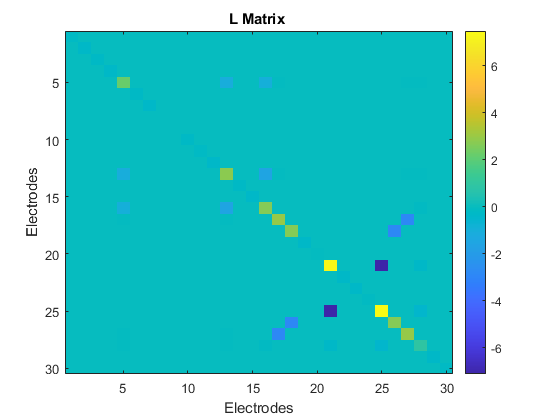

imagesc(L_iter)
title('L Matrix ')
xlabel('Electrodes')
ylabel('Electrodes')
colorbar

This might not work, the data points are too much to reconstruct! We can look at the results